We want to run this in the main QQR directory (since setKroneckerToolsPath is using a relative path, this isn't needed if an absolute path is set and all of the QQR functions are in the path).  You will need to replace the path below to the location of your QQR directory.

cd /Volumes/borggaardT7/Software/MyPublicSoftware/QQR
setKroneckerToolsPath

We create the model system used in *A hierarchy of low-dimensional models for the transient and post-transient cylinder wake, *Noack, Afanasiev, Morzynski, Tadmor, Thiele*, ***J. Fluid Mech.** (2003), vol. 497, pp. 335-363.  


$$\dot{z}_1 = \mu z_1 - z_2 - z_1z_3$$



$$\dot{z}_2 = \mu z_2 + z_1 -z_2z_3$$



$$\dot{z}_3 = -z_3 + z_1^2 + z_2^2$$


For us, using a larger value of $\mu$ than the reference makes the linear part of the system more unstable.  We now write this system in the form

$\dot{\bf z} = {\bf Az} + {\bf Bu} + {\bf N}({\bf z}\otimes {\bf z})$  and corresponding control objective   $J({\bf u}) = \int_0^\infty  {\bf z}(t)^T{\bf Qz}(t) + {\bf u}(t)^T{\bf Ru}(t) dt$,  with ${\bf Q}={\bf Q}^T\geq 0$ and ${\bf R}={\bf R}^T>0$.

mu = 1;
A = [mu -1 0; 1 mu 0; 0 0 -1];
B = [0; 1; 0];
N = [0 0 -1 0 0  0 0 0 0;   % one z1*z3 term is in the third column
     0 0  0 0 0 -1 0 0 0;   % one z2*z3 term is in the sixth column
     1 0  0 0 1  0 0 0 0];  % the z1^2 term is first and the z2^2 term is fifth
Q = eye(3);  R = 1;

N = kronMonomialSymmetrize(N,3,2);   % three states and multiplying a z\otimes z term

We call the QQR function in a similar way as solving LQR in Matlab.  Here we are deciding to use a degree 5 polynomial approximation to the nonlinear feedback law: ${\bf u}={\cal K}({\bf z})$.  This polynomial approximation has the form


$${\bf u}(t) = {\bf k}_1{\bf z} +  {\bf k}_2({\bf z} \otimes {\bf z} ) +  {\bf k}_3({\bf z} \otimes {\bf z} \otimes {\bf z} ) +  {\bf k}_4({\bf z} \otimes {\bf z} \otimes {\bf z}  \otimes {\bf z} ) +  {\bf k}_5({\bf z} \otimes {\bf z} \otimes {\bf z} \otimes {\bf z} \otimes {\bf z} )$$


which is approximated below in the cell array "k" corresponding to the Matlab expression

u = k{1}*z + k{2}*kron(z,z) + k{3}*kron(kron(z,z),z) + k{4}*kron(kron(kron(z,z),z),z) + k{5}*kron(kron(kron(kron(z,z),z),z),z)

or, using kronPolyEval from the KroneckerTools repository,

u = kronPolyEval(k,z,5)

degree = 7;                      % degree of the nonlinear feedback law approximation
[kLQR,vLQR] = lqr(A,B,Q,R);      % compute the LQR gains for comparison
[k,v] = qqr(A,B,Q,R,N,degree);   % approximate the optimal feedback law and 
                                 % corresponding value function using QQR.

First, let's test the LQR solution: u = -kLQR*z (equivalently, u = k{1}*z, note the signs)

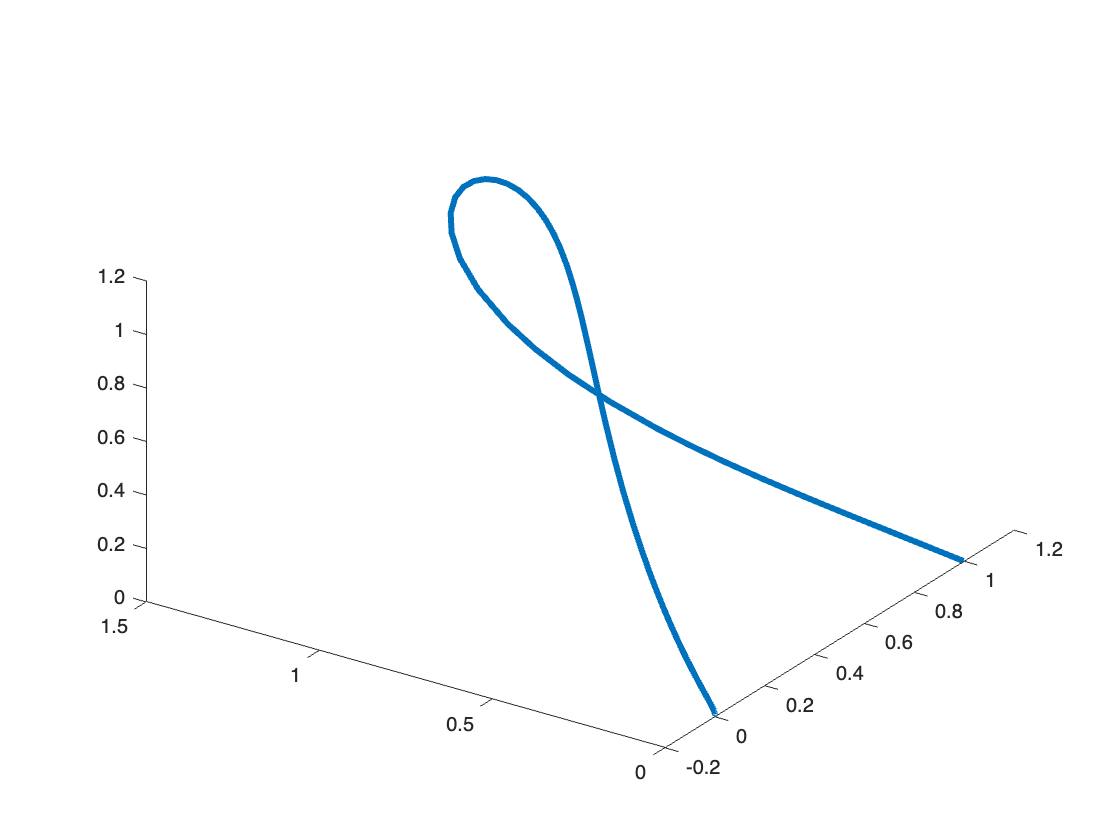

rhsLQR = @(t,z) A*z - B*kLQR*z + N*kron(z,z);
z0  = [1;0;0];
[~,Zlqr] = ode45(rhsLQR,[0 10],z0);
plot3(Zlqr(:,1),Zlqr(:,2),Zlqr(:,3),'LineWidth',3); view([-56.15 39.24]); hold on;

In the plot above, we see that the control can drive the initial state towards the origin effectively.  Now let's evaluate the QQR feedback law.

We are using the function kronPolyEval to evaluate u = k{1}*z + k{2}*kron(z,z) + ... + k{5}*kron(kron(kron(kron(z,z),z),z),z) for the controlled right hand side.

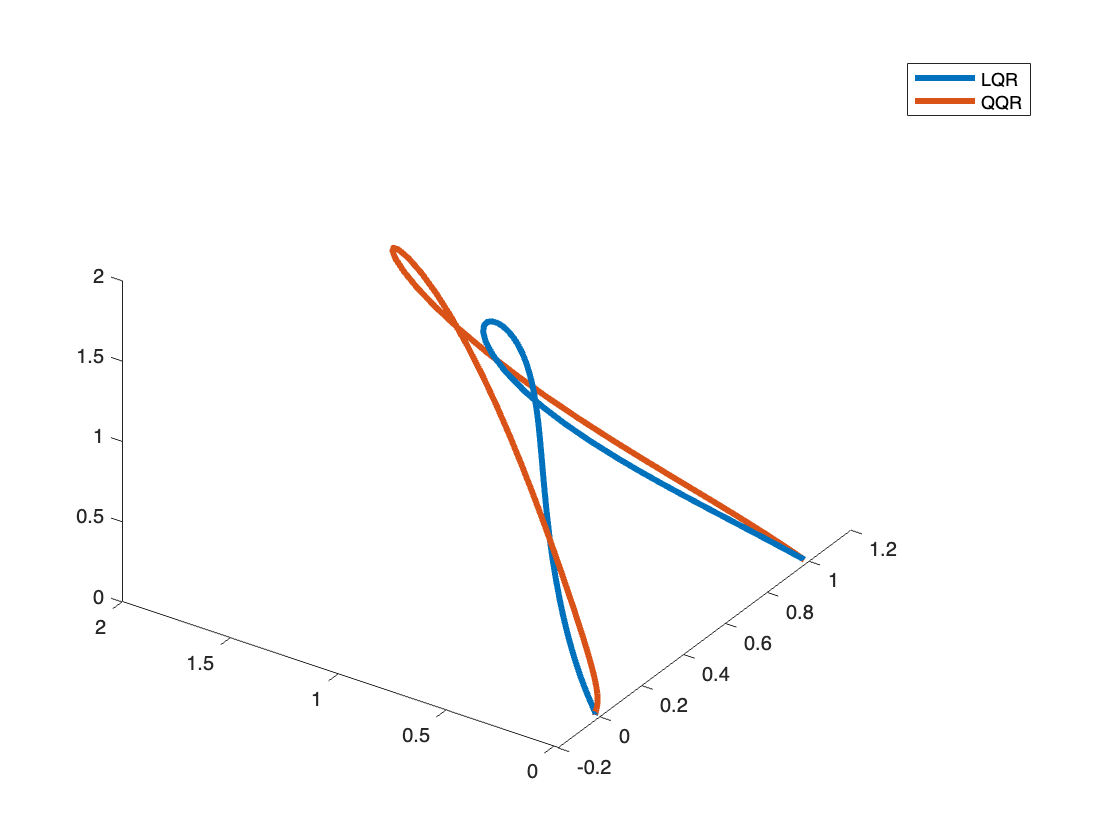

rhs = @(t,z) A*z + B*kronPolyEval(k,z) + N*kron(z,z);
[~,Z] = ode45(rhs,[0 10],z0);
plot3(Z(:,1),Z(:,2),Z(:,3),'LineWidth',3);
legend('LQR','QQR')
view([-56.15 39.24])

The systems obviously follow very different trajectories when using either LQR or QQR controls.  Let's reevaluate these closed-loop systems, but also include the quadratic regulator cost term


$$z_4(t) \equiv \int_0^t {\bf z}(t)^T {\bf Q} {\bf z}(t) + {\bf u}(t)^T{\bf R} {\bf u}(t) dt$$
    

as an auxiliary variable in our systems.  Thus, we add the new equation $\dot{z}_4 = {\bf z}^T(t){\bf Q}{\bf z}(t) + {\bf u}^T(t){\bf R}{\bf u}(t),$ the integrand (running cost) with initial condition $z_4(0) = 0$.  Note we are using ${\bf z}(t)$ to represent the original states, so for us this is z(1:3).  Comparing these two costs gives us a feeling for how much more efficient we can be when we use nonlinear feedback.

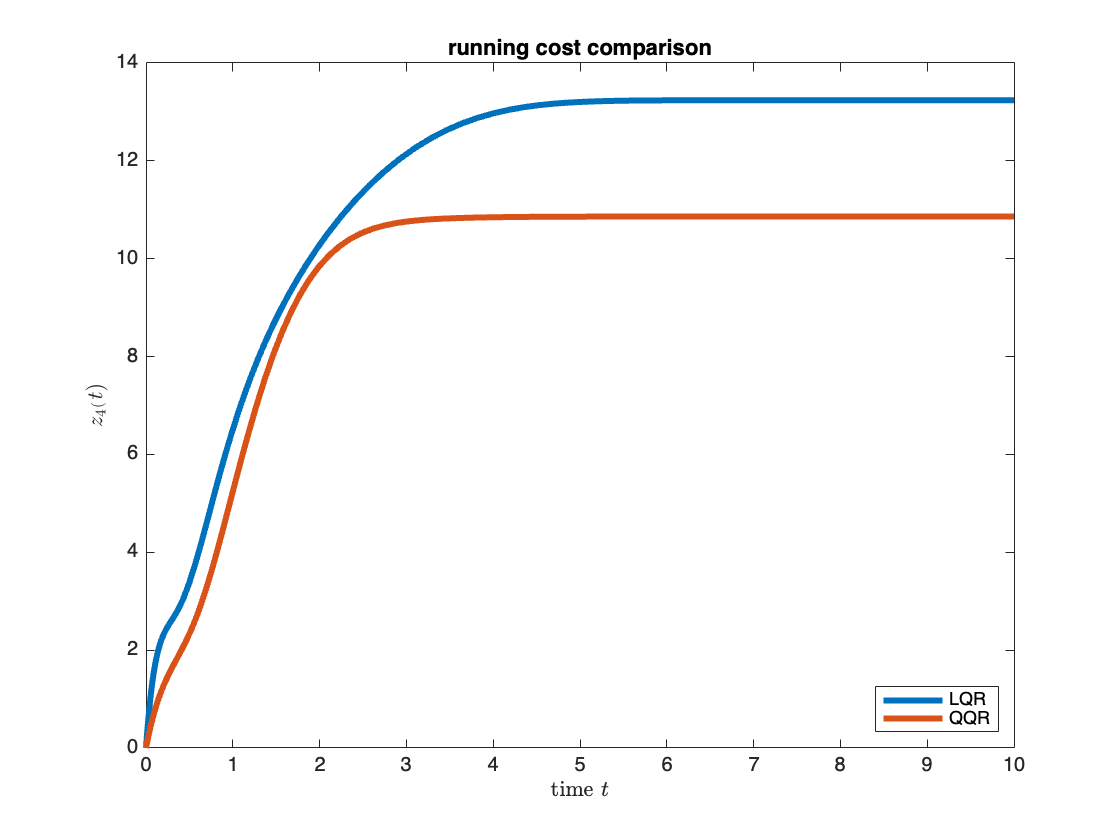

rhsLQR = @(t,z) [A*z(1:3) - B*kLQR*z(1:3) + N*kron(z(1:3),z(1:3));
                 z(1:3).'*Q*z(1:3) + (kLQR*z(1:3)).'*R*(kLQR*z(1:3))];
[Tlqr,Zlqr] = ode45(rhsLQR,[0 10],[z0;0]);

rhs = @(t,z) [A*z(1:3) + B*kronPolyEval(k,z(1:3)) + N*kron(z(1:3),z(1:3)); 
              z(1:3).'*Q*z(1:3) + (kronPolyEval(k,z(1:3))).'*R*(kronPolyEval(k,z(1:3)))];
[T,Z] = ode45(rhs,[0 10],[z0;0]);

figure
plot(Tlqr,Zlqr(:,end),T,Z(:,end),'LineWidth',3)
legend('LQR','QQR','Location','SouthEast')
xlabel('time $t$','Interpreter','latex'); ylabel('$z_4(t)$','Interpreter','latex')
title('running cost comparison')

We see in the plot above that the quadratic regulator cost using QQR with degree=5 settles at a value between 11 and 12.  We can compare the final value at $t=10$

Z(end,end)

ans = 10.8620

with the degree 6 polynomial approximation to the value function from this initial condition

kronPolyEval(v,z0,degree+1)

ans = 10.5100

There is a significant difference between these values.  Rerunning this script using degree=7 gives us corresponding values of Z(end,end)=10.8620 and kronPolyEval(v,z0,8)=10.5100 which are in better agreement.  

The improvement in quadratic regulator cost associated with a degree=5 feedback approximation (11.2237) to that of the degree=7 feedback approximation (10.8620) can be weighed against the tradeoff in computational cost and the more expensive evaluation of the higher degree feedback terms. 

It was clear from the plots above that the QQR solution lead to states that were much larger over their evolution.  We can compare the controls to explain the differences in quadratic regulator costs.

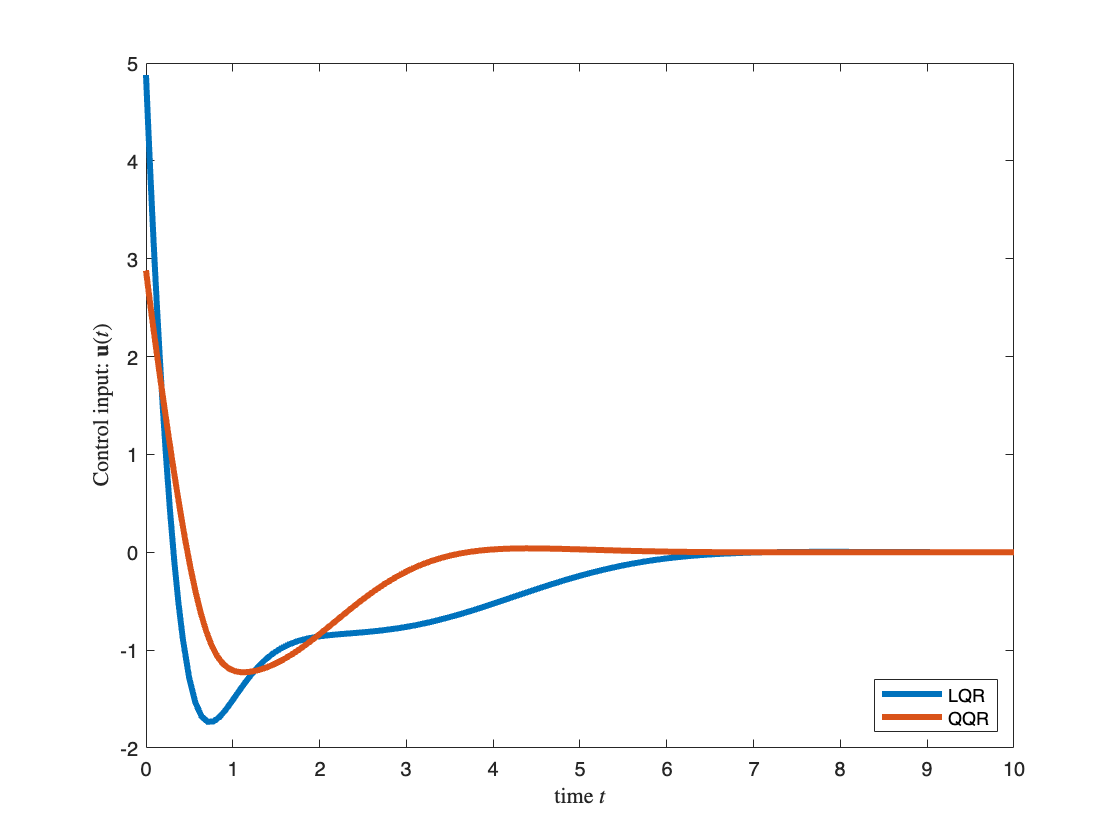

uLQR = k{1}*Zlqr(:,1:3).';
uQQR = zeros(1,size(T,1));
for i=1:size(T,1)
  uQQR(i) = kronPolyEval(k,Z(i,1:3).',degree);
end

plot(Tlqr,uLQR,T,uQQR,'LineWidth',3)
legend('LQR','QQR','Location','SouthEast') 
xlabel('time $t$','Interpreter','latex')  
ylabel('Control input: ${\bf u}(t)$','Interpreter','latex')